xyz_camera_calibration.mlx

Alex Elias

Uses UWB distance readings to calculate XYZ of camera/UWB calibration checkerboard

## Read in UWB readings from ROS

bag = rosbag('2021-09-13-11-30-10.bag')

bag =   BagSelection with properties:

           FilePath: 'C:\Users\eliasa3\Dropbox\RPI\PhD\Swarm Robotics\ARM-20-02-C-15-Swarm-Robotics\matlab_scripts\2021-09-13-11-30-10.bag'
          StartTime: 1.6315e+09
            EndTime: 1.6315e+09
        NumMessages: 16033
    AvailableTopics: [3×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [16033×4 table]


bag.AvailableTopics

ans = 3×3 table
                     NumMessages       MessageType                                                                                                  MessageDefinition                                                                                            
                     ___________    _________________    ________________________________________________________________________________________________________________________________________________________________________________________________________

    /rosout                4        rosgraph_msgs/Log    {'int8 INFO↵int8 WARN↵int8 ERROR↵int8 FATAL↵std_msgs/Header Header↵  uint32 Seq↵  Time Stamp↵  char FrameId↵int8 Level↵char Name↵char Msg↵char File↵char Function↵uint32 Line↵char[] Topics↵'}
    /uwb_serial_x       8015        std_msgs/String      {0×0 char                 


bSel_x = select(bag,'Topic','/uwb_serial_x');
msgs_x = readMessages(bSel_x);
t_x = bSel_x.MessageList.Time;

bSel_y = select(bag,'Topic','/uwb_serial_y');
msgs_y = readMessages(bSel_y);
t_y = bSel_y.MessageList.Time;

## Parse readings, find average distances and statistics

[anchor_names, anchor_locs] = anchor_info(msgs_x)

anchor_names = 4×1 string array
    "2A32"
    "29EF"
    "2ED1"
    "0D40"


anchor_locs =    10.9700   10.7600    2.7600         0
         0    4.2400    4.3200         0
    3.2500    3.1400    3.2900    3.5700


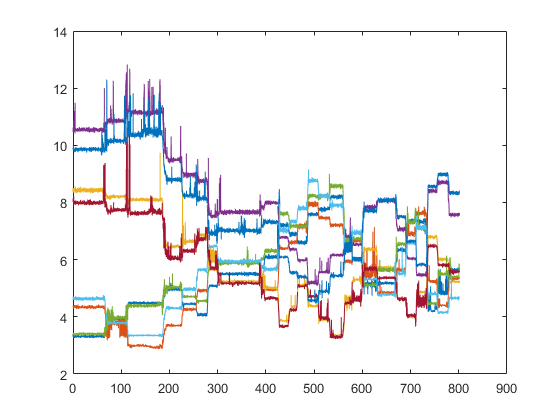

dist_mat_x = get_distances(msgs_x, anchor_names);
dist_mat_y = get_distances(msgs_y, anchor_names);

t_0 = min([t_x; t_y]);
t_x_offset = t_x-t_0;
t_y_offset = t_y-t_0;

plot(t_x_offset, dist_mat_x); hold on
plot(t_y_offset, dist_mat_y); hold off


t_start = [5  86 126 208 230 263 284 310 401 430 453 470 491 517 538 565 581 612 642 674 698 718 742 765 785] 

t_start =      5    86   126   208   230   263   284   310   401   430   453   470   491   517   538   565   581   612   642   674   698   718   742   765   785


t_end =   [57 95 140 220 250 272 294 343 418 445 460 479 500 525 554 577 594 619 665 688 707 730 750 772 800]

t_end =     57    95   140   220   250   272   294   343   418   445   460   479   500   525   554   577   594   619   665   688   707   730   750   772   800


N_pts = length(t_start)

N_pts = 25


avg_dist_mat_x = nan(4, N_pts);
avg_dist_mat_y = nan(4, N_pts);
std_mat_x = nan(4, N_pts);
std_mat_y = nan(4, N_pts);

for i = 1:N_pts
    ind_x =  t_x_offset >= t_start(i) & t_x_offset <= t_end(i);
    ind_y =  t_y_offset >= t_start(i) & t_y_offset <= t_end(i);
    
    t_x_i = t_x_offset(ind_x);
    dist_mat_x_i = dist_mat_x(ind_x, :);
    t_y_i = t_y_offset(ind_y);
    dist_mat_y_i = dist_mat_y(ind_y, :);
    
    
%     figure; plot(t_x_i, dist_mat_x_i)
%     figure; plot(t_y_i, dist_mat_y_i)
    
    avg_dists_x = mean(dist_mat_x_i,'omitnan')
    std_x = std(dist_mat_x_i,'omitnan')*1e3
    
    avg_dists_y = mean(dist_mat_y_i,'omitnan')
    std_y = std(dist_mat_y_i,'omitnan')*1e3
    
    avg_dist_mat_x(:, i) = avg_dists_x;
    avg_dist_mat_y(:, i) = avg_dists_y;
    
    std_mat_x(:,i) = std_x;
    std_mat_y(:,i) = std_y;
end

avg_dists_x =     3.3170    4.3423    8.4293   10.5446


std_x =    22.0648   27.6477   40.6575   35.4681


avg_dists_y =     3.4020    4.6340    7.9871    9.8601


std_y =    21.7003   29.6799   35.5609   32.7776


avg_dists_x =     3.9134    3.7778    8.2048   10.8557


std_x =    21.5240   46.7308   26.5052   40.5870


avg_dists_y =     3.9649    3.7874    7.7389   10.1572


std_y =    35.6155   19.9190   33.5685   39.0509


avg_dists_x =     4.4863    2.9929    8.0973   11.1561


std_x =    21.7356   21.7668   25.2140   41.1996


avg_dists_y =     4.3896    3.3479    7.6174   10.3639


std_y =    29.9018   15.0197   35.4898   46.1647


avg_dists_x =     4.9566    3.6948    6.4579    9.4947


std_x =    21.7177   18.1489   25.2682   29.8534


avg_dists_y =     5.0354    4.3013    6.0621    8.8013


std_y =    23.3316   19.3131   34.3649   34.9204


avg_dists_x =     4.4509    4.2588    6.6407    8.9739


std_x =    18.3728   28.3652   71.1335   67.8948


avg_dists_y =     4.7035    4.9721    6.3078    8.2652


std_y =    19.7379   31.5359   34.0139   93.9685


avg_dists_x =     4.0811    4.9198    6.8651    8.7541


std_x =    29.1623   29.0284   26.6582   32.6471


avg_dists_y =     4.5561    5.6438    6.7141    8.1437


std_y =    17.9697   24.5214   37.1421   38.1732


avg_dists_x =     5.0854    5.6573    6.1560    7.5294


std_x =    20.2693   19.7339  158.5859   51.0460


avg_dists_y =     5.7168    6.4585    5.7301    6.9253


std_y =    19.7908   22.7581   59.5182   43.8652


avg_dists_x =     5.5019    5.2155    5.2304    7.6624


std_x =    25.5163   19.8279   25.0086   37.6408


avg_dists_y =     5.8793    5.9421    5.1749    7.0199


std_y =    22.7331   27.1995   44.7971   35.4413


avg_dists_x =     6.0898    4.9431    5.0187    7.9957


std_x =    33.1743   20.4981   25.2268   34.2736


avg_dists_y =     6.3125    5.6634    4.6615    7.3179


std_y =    33.3852   29.2983   29.0075   36.9375


avg_dists_x =     7.2071    6.3930    3.8677    6.7789


std_x =    37.5479   23.4234   30.9018   25.4660


avg_dists_y =     7.6063    7.0315    3.6711    6.0902


std_y =    36.5898   49.6253   27.5519   19.7782


avg_dists_x =     6.8938    6.6029    4.3573    6.3699


std_x =    39.5601   35.6368   22.7731   26.3473


avg_dists_y =     7.1849    7.3451    4.2410    5.5513


std_y =    29.7206   30.4432   26.2734   29.4845


avg_dists_x =     6.6022    7.1730    5.1103    5.9789


std_x =    31.5419   42.0927   20.2485   24.8340


avg_dists_y =     7.1658    7.8004    5.0596    5.4039


std_y =    37.5358   39.6023   15.6443   28.5883


avg_dists_x = 1×4
    7.5894    7.9400    4.3816    5.1919


std_x = 1×4
   30.1270   43.8844   26.6863   29.2565


avg_dists_y = 1×4
    8.2362    8.7698    4.7207    4.5841


std_y = 1×4
   34.5298   38.9048   34.8609   27.6371


avg_dists_x = 1×4
    7.7630    7.4552    3.9080    5.5633


std_x = 1×4
   35.8407   28.0585   30.7048   25.0960


avg_dists_y = 1×4
    8.2290    8.2284    3.9664    4.8906


std_y = 1×4
   35.9183   35.6058   28.9147   22.4648


avg_dists_x = 1×4
    8.1951    7.2064    3.3516    6.1626


std_x = 1×4
   35.8543   30.4132   20.6741   22.8150


avg_dists_y = 1×4
    8.5732    7.9029    3.2986    5.4382


std_y = 1×4
   35.1388   35.6201   40.6566   29.8186


avg_dists_x = 1×4
    6.6788    5.9413    4.5777    6.8451


std_x = 1×4
   26.5109   28.7869  121.4352  114.0544


avg_dists_y = 1×4
    6.6617    6.4209    4.4950    6.4218


std_y = 1×4
   46.3152   31.6758   41.0779  168.6384


avg_dists_x = 1×4
    6.0591    6.6751    5.2986    6.5285


std_x = 1×4
   20.9631   38.3674   33.2189   26.9110


avg_dists_y = 1×4
    6.7262    6.9369    4.6295    5.9872


std_y = 1×4
   29.3174   38.7258   79.0798   27.6813


avg_dists_x = 1×4
    5.1401    5.4596    6.3644    7.8370


std_x = 1×4
   37.0074   78.0542   30.4857   37.6232


avg_dists_y = 1×4
    5.1087    5.3141    5.6870    7.7197


std_y = 1×4
   19.1804   18.0573   40.1212   38.0004


avg_dists_x = 1×4
    5.1808    4.8525    5.7230    8.0730


std_x = 1×4
   23.9017   20.8066   24.4083   33.1458


avg_dists_y = 1×4
    5.6468    4.7775    5.3630    8.0799


std_y = 1×4
   34.5769   23.3576   22.9286   34.7918


avg_dists_x = 1×4
    6.3365    5.6543    4.6621    7.0717


std_x = 1×4
   32.5902   50.4817   16.3066   38.9648


avg_dists_y = 1×4
    6.5410    5.5487    4.6175    7.5014


std_y = 1×4
   31.6068  102.8495   31.7392   32.7012


avg_dists_x = 1×4
    7.3483    6.8959    3.9884    6.0391


std_x = 1×4
   41.6850   42.0779   18.0456   23.0605


avg_dists_y = 1×4
    7.3060    6.5796    4.0482    6.6467


std_y = 1×4
   38.2129   31.1182   24.2449   27.1492


avg_dists_x = 1×4
    7.3271    7.6288    4.8701    5.4672


std_x = 1×4
   43.4712   48.9071   22.3605   27.9544


avg_dists_y = 1×4
    7.0920    7.1132    4.4891    5.8282


std_y = 1×4
   39.9706   45.5034  118.4210   25.9923


avg_dists_x = 1×4
    4.2052    5.2365    6.7901    8.4086


std_x = 1×4
   20.3747   24.7059   28.7501   35.4266


avg_dists_y = 1×4
    4.4661    4.8018    6.4754    8.5603


std_y = 1×4
   20.9577   27.1319   30.4790   28.4188


avg_dists_x = 1×4
    4.8361    4.4036    6.0067    8.7081


std_x = 1×4
   54.5148   17.3653   27.3316   32.4503


avg_dists_y = 1×4
    5.4947    4.1544    5.8131    8.9794


std_y = 1×4
   25.7480   21.6451   30.8593   32.0726


avg_dists_x = 1×4
    5.6447    5.3433    5.2281    7.5714


std_x = 1×4
   27.3105   25.4006   17.8082   28.8256


avg_dists_y = 1×4
    5.4021    4.6588    5.5741    8.3267


std_y = 1×4
   20.4436   27.6051   29.2014   32.1385



avg_dist_mat_x

avg_dist_mat_x = 4×25
    3.3170    3.9134    4.4863    4.9566    4.4509    4.0811    5.0854    5.5019    6.0898    7.2071    6.8938    6.6022    7.5894    7.7630    8.1951    6.6788    6.0591    5.1401    5.1808    6.3365    7.3483    7.3271    4.2052    4.8361    5.6447
    4.3423    3.7778    2.9929    3.6948    4.2588    4.9198    5.6573    5.2155    4.9431    6.3930    6.6029    7.1730    7.9400    7.4552    7.2064    5.9413    6.6751    5.4596    4.8525    5.6543    6.8959    7.6288    5.2365    4.4036    5.3433
    8.4293    8.2048    8.0973    6.4579    6.6407    6.8651    6.1560    5.2304    5.0187    3.8677    4.3573    5.1103    4.3816    3.9080    3.3516    4.5777    5.2986    6.3644    5.7230    4.6621    3.9884    4.8701    6.7901    6.0067    5.2281
   10.5446   10.8557   11.1561    9.4947    8.9739    8.7541    7.5294    7.6624    7.9957    6.7789    6.3699    5.9789    5.1919    5.5633    6.1626    6.8451    6.5285    7.8370    8.0730    7.0717    6.0391    5.4672    8

avg_dist_mat_y

avg_dist_mat_y = 4×25
    3.4020    3.9649    4.3896    5.0354    4.7035    4.5561    5.7168    5.8793    6.3125    7.6063    7.1849    7.1658    8.2362    8.2290    8.5732    6.6617    6.7262    5.1087    5.6468    6.5410    7.3060    7.0920    4.4661    5.4947    5.4021
    4.6340    3.7874    3.3479    4.3013    4.9721    5.6438    6.4585    5.9421    5.6634    7.0315    7.3451    7.8004    8.7698    8.2284    7.9029    6.4209    6.9369    5.3141    4.7775    5.5487    6.5796    7.1132    4.8018    4.1544    4.6588
    7.9871    7.7389    7.6174    6.0621    6.3078    6.7141    5.7301    5.1749    4.6615    3.6711    4.2410    5.0596    4.7207    3.9664    3.2986    4.4950    4.6295    5.6870    5.3630    4.6175    4.0482    4.4891    6.4754    5.8131    5.5741
    9.8601   10.1572   10.3639    8.8013    8.2652    8.1437    6.9253    7.0199    7.3179    6.0902    5.5513    5.4039    4.5841    4.8906    5.4382    6.4218    5.9872    7.7197    8.0799    7.5014    6.6467    5.8282    8

std_mat_x

std_mat_x = 4×25
   22.0648   21.5240   21.7356   21.7177   18.3728   29.1623   20.2693   25.5163   33.1743   37.5479   39.5601   31.5419   30.1270   35.8407   35.8543   26.5109   20.9631   37.0074   23.9017   32.5902   41.6850   43.4712   20.3747   54.5148   27.3105
   27.6477   46.7308   21.7668   18.1489   28.3652   29.0284   19.7339   19.8279   20.4981   23.4234   35.6368   42.0927   43.8844   28.0585   30.4132   28.7869   38.3674   78.0542   20.8066   50.4817   42.0779   48.9071   24.7059   17.3653   25.4006
   40.6575   26.5052   25.2140   25.2682   71.1335   26.6582  158.5859   25.0086   25.2268   30.9018   22.7731   20.2485   26.6863   30.7048   20.6741  121.4352   33.2189   30.4857   24.4083   16.3066   18.0456   22.3605   28.7501   27.3316   17.8082
   35.4681   40.5870   41.1996   29.8534   67.8948   32.6471   51.0460   37.6408   34.2736   25.4660   26.3473   24.8340   29.2565   25.0960   22.8150  114.0544   26.9110   37.6232   33.1458   38.9648   23.0605   27.9544   35.4266

std_mat_y

std_mat_y = 4×25
   21.7003   35.6155   29.9018   23.3316   19.7379   17.9697   19.7908   22.7331   33.3852   36.5898   29.7206   37.5358   34.5298   35.9183   35.1388   46.3152   29.3174   19.1804   34.5769   31.6068   38.2129   39.9706   20.9577   25.7480   20.4436
   29.6799   19.9190   15.0197   19.3131   31.5359   24.5214   22.7581   27.1995   29.2983   49.6253   30.4432   39.6023   38.9048   35.6058   35.6201   31.6758   38.7258   18.0573   23.3576  102.8495   31.1182   45.5034   27.1319   21.6451   27.6051
   35.5609   33.5685   35.4898   34.3649   34.0139   37.1421   59.5182   44.7971   29.0075   27.5519   26.2734   15.6443   34.8609   28.9147   40.6566   41.0779   79.0798   40.1212   22.9286   31.7392   24.2449  118.4210   30.4790   30.8593   29.2014
   32.7776   39.0509   46.1647   34.9204   93.9685   38.1732   43.8652   35.4413   36.9375   19.7782   29.4845   28.5883   27.6371   22.4648   29.8186  168.6384   27.6813   38.0004   34.7918   32.7012   27.1492   25.9923   28.4188

## Localize checkerboard

cal_map = antenna_cal_values()

cal_map =   Map with properties:

        Count: 18
      KeyType: char
    ValueType: double



anchor_offsets = [  cal_map(anchor_names(1))
                    cal_map(anchor_names(2))
                    cal_map(anchor_names(3))
                    cal_map(anchor_names(4))]

anchor_offsets =     0.0650
    0.0420
    0.0620
    0.0940


tag_offset_x = cal_map('2FFD')

tag_offset_x = 0.0470

tag_offset_y = cal_map('15ED')

tag_offset_y = 0.0390


dists_x_cal = avg_dist_mat_x + anchor_offsets + tag_offset_x

dists_x_cal =     3.4290    4.0254    4.5983    5.0686    4.5629    4.1931    5.1974    5.6139    6.2018    7.3191    7.0058    6.7142    7.7014    7.8750    8.3071    6.7908    6.1711    5.2521    5.2928    6.4485    7.4603    7.4391    4.3172    4.9481    5.7567
    4.4313    3.8668    3.0819    3.7838    4.3478    5.0088    5.7463    5.3045    5.0321    6.4820    6.6919    7.2620    8.0290    7.5442    7.2954    6.0303    6.7641    5.5486    4.9415    5.7433    6.9849    7.7178    5.3255    4.4926    5.4323
    8.5383    8.3138    8.2063    6.5669    6.7497    6.9741    6.2650    5.3394    5.1277    3.9767    4.4663    5.2193    4.4906    4.0170    3.4606    4.6867    5.4076    6.4734    5.8320    4.7711    4.0974    4.9791    6.8991    6.1157    5.3371
   10.6856   10.9967   11.2971    9.6357    9.1149    8.8951    7.6704    7.8034    8.1367    6.9199    6.5109    6.1199    5.3329    5.7043    6.3036    6.9861    6.6695    7.9780    8.2140    7.2127    6.1801    5.6082    8.5496   

dists_y_cal = avg_dist_mat_y + anchor_offsets + tag_offset_y

dists_y_cal =     3.5060    4.0689    4.4936    5.1394    4.8075    4.6601    5.8208    5.9833    6.4165    7.7103    7.2889    7.2698    8.3402    8.3330    8.6772    6.7657    6.8302    5.2127    5.7508    6.6450    7.4100    7.1960    4.5701    5.5987    5.5061
    4.7150    3.8684    3.4289    4.3823    5.0531    5.7248    6.5395    6.0231    5.7444    7.1125    7.4261    7.8814    8.8508    8.3094    7.9839    6.5019    7.0179    5.3951    4.8585    5.6297    6.6606    7.1942    4.8827    4.2354    4.7398
    8.0881    7.8399    7.7184    6.1631    6.4088    6.8151    5.8311    5.2759    4.7625    3.7721    4.3420    5.1606    4.8217    4.0674    3.3996    4.5960    4.7305    5.7880    5.4640    4.7185    4.1492    4.5901    6.5764    5.9141    5.6751
    9.9931   10.2902   10.4969    8.9343    8.3982    8.2767    7.0583    7.1529    7.4509    6.2232    5.6843    5.5369    4.7171    5.0236    5.5712    6.5548    6.1202    7.8527    8.2129    7.6344    6.7797    5.9612    8.6933   


[pos, err] = tag_pair_min_z(dists_x_cal, dists_y_cal, [0.604; 0], [0; 0.669], anchor_locs)

pos =     9.9617   10.0015   10.2300    8.4978    8.2584    8.1795    6.7161    6.7776    6.7044    5.0809    5.0961    5.0043    3.9076    4.0377    4.0625    5.9020    5.0753    6.6317    6.7040    6.4486    5.1053    4.0981    8.3312    7.3368    6.6228
    0.5761    1.7302    2.7964    2.6794    1.4835    0.4993    0.4429    1.6917    2.7191    2.7050    1.5792    0.3258    0.6065    1.6024    2.8951    2.2030    0.7954    1.2481    2.3897    2.9904    3.0103    1.3783    1.1817    2.8917    2.8179
    0.1835    0.0470    0.1923    0.2556    0.2346    0.2392    0.1781    0.2881    0.2288    0.2491    0.2613    0.2128    0.2182    0.2257    0.2435    0.2101    0.2586    0.1748    0.2861    0.2207    0.1309    0.1584    0.2661    0.2732    0.2542
    1.3191    1.1273    1.4629    1.5826    1.5212    1.5572    1.1777    1.6519    1.5494    1.5086    1.5482    1.3904    1.5036    1.4718    1.5218    1.9863    0.1481   -0.5161   -0.4878    2.5499    3.1484    5.1721    2.2935   -0.6759 

err =     0.0323
    0.0949
    0.0230
    0.0069
    0.0126
    0.0088
    0.0313
    0.0102
    0.0081
    0.0121


pos(3,:) = pos(3,:) - 0.210

pos =     9.9617   10.0015   10.2300    8.4978    8.2584    8.1795    6.7161    6.7776    6.7044    5.0809    5.0961    5.0043    3.9076    4.0377    4.0625    5.9020    5.0753    6.6317    6.7040    6.4486    5.1053    4.0981    8.3312    7.3368    6.6228
    0.5761    1.7302    2.7964    2.6794    1.4835    0.4993    0.4429    1.6917    2.7191    2.7050    1.5792    0.3258    0.6065    1.6024    2.8951    2.2030    0.7954    1.2481    2.3897    2.9904    3.0103    1.3783    1.1817    2.8917    2.8179
   -0.0265   -0.1630   -0.0177    0.0456    0.0246    0.0292   -0.0319    0.0781    0.0188    0.0391    0.0513    0.0028    0.0082    0.0157    0.0335    0.0001    0.0486   -0.0352    0.0761    0.0107   -0.0791   -0.0516    0.0561    0.0632    0.0442
    1.3191    1.1273    1.4629    1.5826    1.5212    1.5572    1.1777    1.6519    1.5494    1.5086    1.5482    1.3904    1.5036    1.4718    1.5218    1.9863    0.1481   -0.5161   -0.4878    2.5499    3.1484    5.1721    2.2935   -0.6759 

multilateration_err_cm = 1e2* sqrt(err/8)

multilateration_err_cm =     6.3531
   10.8910
    5.3668
    2.9273
    3.9652
    3.3136
    6.2518
    3.5664
    3.1846
    3.8910


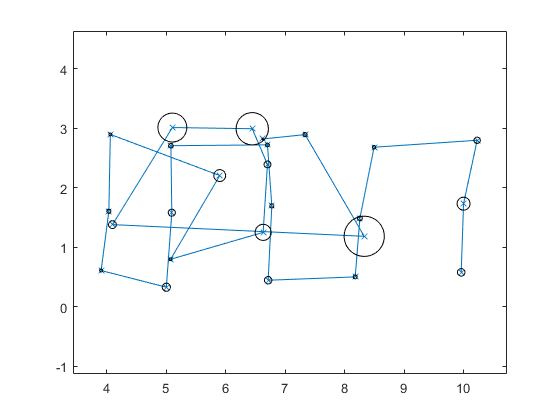

plot(pos(1,:), pos(2,:), '-x'); hold on
for i = 1:width(pos)
    plot_circle(pos(1,i), pos(2,i), 1e-2*multilateration_err_cm(i));
end
hold off
axis equal padded

1e2*std(pos(3,:))

ans = 5.3774

## Write list of XYZ positions to CSV file

csv_mat = [pos(1:3,:)' multilateration_err_cm]

csv_mat =     9.9617    0.5761   -0.0265    6.3531
   10.0015    1.7302   -0.1630   10.8910
   10.2300    2.7964   -0.0177    5.3668
    8.4978    2.6794    0.0456    2.9273
    8.2584    1.4835    0.0246    3.9652
    8.1795    0.4993    0.0292    3.3136
    6.7161    0.4429   -0.0319    6.2518
    6.7776    1.6917    0.0781    3.5664
    6.7044    2.7191    0.0188    3.1846
    5.0809    2.7050    0.0391    3.8910


filename = "xyz_camera_cal_uwb_" + datestr(datetime('now'), 'yyyy-mm-dd_HH-MM-SS') + ".csv"

filename = "xyz_camera_cal_uwb_2021-09-13_23-41-26.csv"

writematrix(csv_mat, filename)

function [anchor_names, anchor_locs] = anchor_info(msgs)
% Find the 4 anchors
for i = 1:length(msgs)
    line = msgs{i}.Data;
    line_sp = split(line, ',');
    if line_sp{2} == '4' % Got 4 readings this line
        anchor_names = string([line_sp{4}; line_sp{10}; line_sp{16}; line_sp{22}]);
        line_sp = str2double(line_sp);
        anchor_locs = [line_sp(5) line_sp(11) line_sp(17) line_sp(23)
                       line_sp(6) line_sp(12) line_sp(18) line_sp(24)
                       line_sp(7) line_sp(13) line_sp(19) line_sp(25)];
        break
    end
end
end

function dist_mat = get_distances(msgs, anchors)
dist_mat = NaN(length(msgs), 4);
for i = 1:length(msgs)
        line = msgs{i}.Data;
        if line == ""
            continue
        end
        data = split(line, ',');
        % Anchor labels are at 4,10,16,22
        % Anchor distances are at 8, 14, 20, 26
        N_anch_i = str2double(data{2});
        
        if N_anch_i >= 1
            dist_mat(i, anchors == data{4}) = str2double(data{8});
        end
        if N_anch_i >= 2
            dist_mat(i, anchors == data{10}) = str2double(data{14});
        end
        if N_anch_i >= 3
            dist_mat(i, anchors == data{16}) = str2double(data{20});
        end
        if N_anch_i == 4
            dist_mat(i, anchors == data{22}) = str2double(data{26});
        end
end
end

function h = plot_circle(x,y,r)
d = r*2;
px = x-r;
py = y-r;
h = rectangle('Position',[px py d d],'Curvature',[1,1]);
end